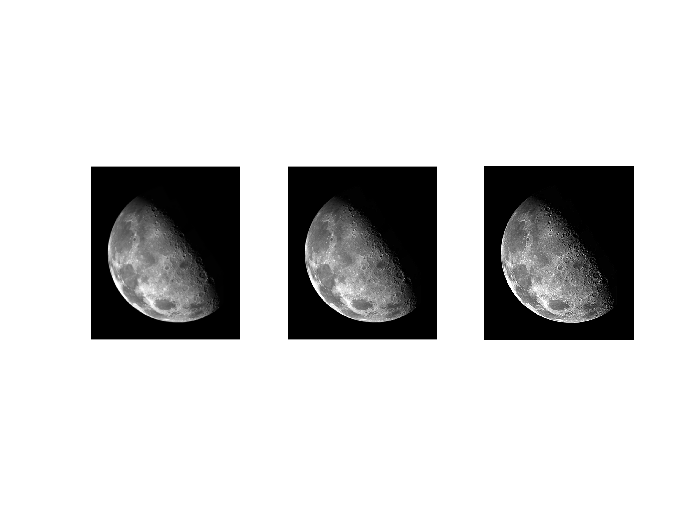

clear;clc;
f=imread("Fig0217(a).tif");
f2=tofloat(f);%将f转化为浮点型数据
figure;
subplot(1,3,1);
imshow(f);
w4=fspecial('laplacian',0);%拉普拉斯滤波器
w8=[1 1 1;1 -8 1;1 1 1];
g4=f2-imfilter(f2,w4,'replicate');
g8=f2-imfilter(f2,w8,'replicate');
subplot(1,3,2);imshow(g4);
subplot(1,3,3);imshow(g8);